23.39

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
a = 0.17;
tau = 0.015;
rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);
s = tf('s');
P = mot.k / (mot.T * s + 1);
C = (1 + tau * s) / (s * (1 + a * tau * s));

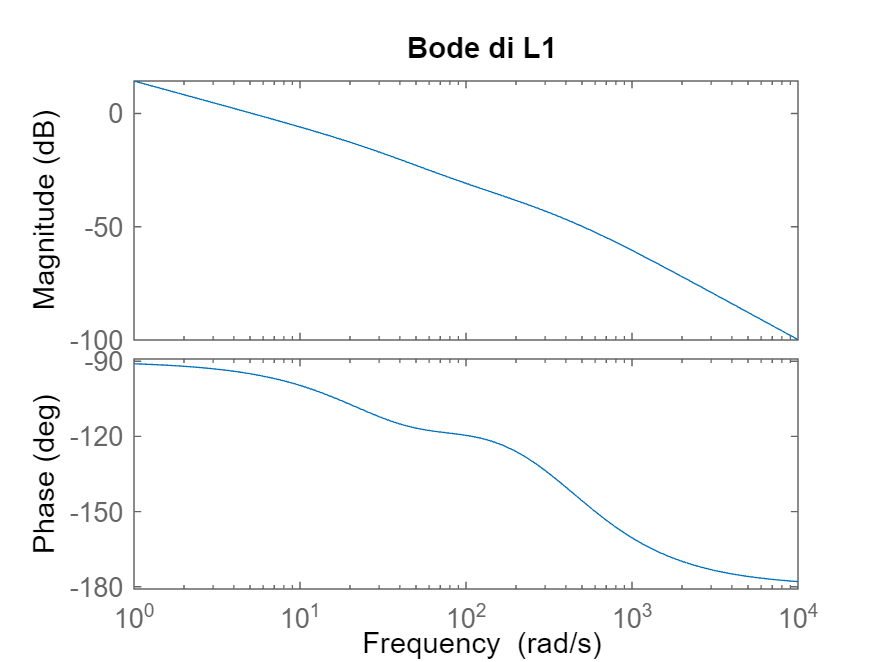

L1 = P * C;
close all
figure(1)
bode(L1)
title("Bode di L1")

[~, phim1, ~, wgc1] = margin(L1)

phim = 84.8785

wgc = 5.1538

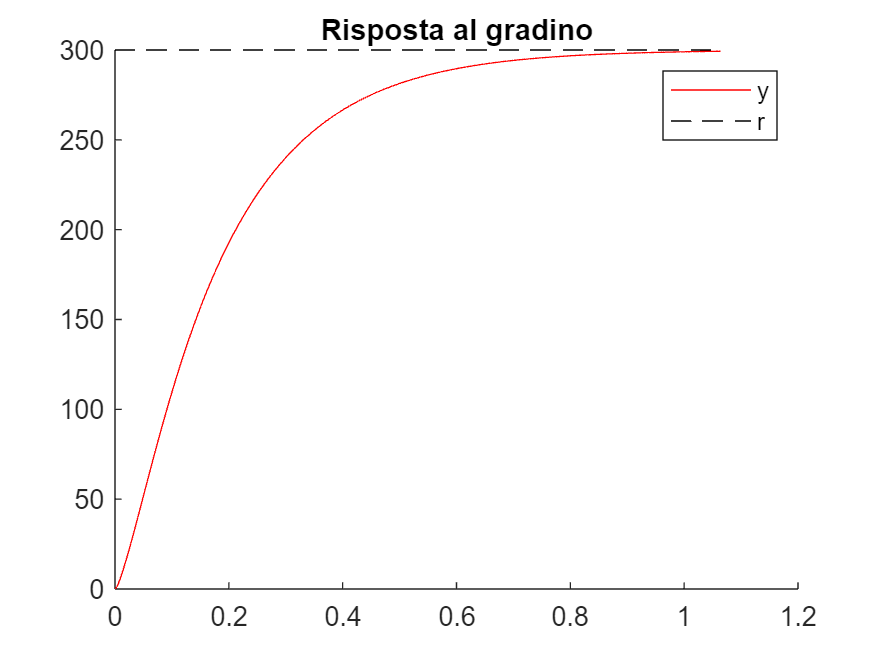

T1 = minreal(feedback(L1, 1), 1e-6);
A = 300 * rpm2rads; % [rad/s]
opt = stepDataOptions("StepAmplitude", A);
[y, t] = step(T1, opt);
close all
figure(2)
hold on
plot(t, y * rads2rpm, "r")
plot([t(1), t(end)], [300, 300], "k--")
title("Risposta al gradino")
legend("y", "r")

stepinfo(y, t, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.3832
    TransientTime: 0.5298
     SettlingTime: 0.5298
      SettlingMin: 28.2347
      SettlingMax: 31.3434
        Overshoot: 0
       Undershoot: 0
             Peak: 31.3434
         PeakTime: 1.0640


Il guadagno è pari al reciproco del modulo di L in j * wgc'

wgc1 = 2 * pi * 25;
k = 1 / abs(freqresp(L1, wgc1));
L2 = k * L1;
[~, phim2, ~, wgc2] = margin(L2)

phim2 = 57.1551

wgc2 = 157.0794

23.51